# Hypothesis testing

clc;
close all;
clear variables;

set(groot,'defaulttextinterpreter','latex');  
set(groot, 'defaultAxesTickLabelInterpreter','latex');  
set(groot, 'defaultLegendInterpreter','latex');

## Parameters

ma = [3; -1]; 
mb = [10; -4];

sigma_a = [1.7; 3];
sigma_b = [3; 1.4];

rho_a = 0.6;
rho_b = 0.7;

num_a = 5000;
sum_b = 5000;

## Samples

A = Samples(ma, sigma_a, rho_a,  num_a);
B = Samples(mb, sigma_b, rho_b, sum_b);

## Plotting


figure();
grid on; hold on; axis equal;
labels = {};

A.plot('b.'); labels{end+1} = 'A';
B.plot('r.'); labels{end+1} = 'B';

title('Samples with constant pdf countours');
xlabel('$x_1$', "Interpreter","latex")
ylabel('$x_2$', "Interpreter","latex")

syms x_1 x_2 real
X = [x_1; x_2];

line_width = 3;


$$f(X) = const$$


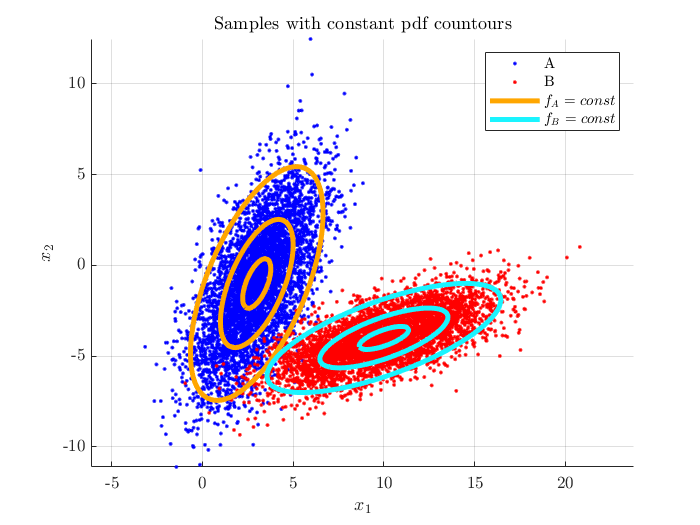

for const_pdf_val = [0.1 0.5 0.9]
    fimplicit(exp(-0.5 * (X - A.M)' * A.cov_mat ^ (-1) * (X - A.M)) == const_pdf_val, 'Color', '#FFA600', 'LineWidth', line_width)
    fimplicit(exp(-0.5 * (X - B.M)' * B.cov_mat ^ (-1) * (X - B.M)) == const_pdf_val, 'Color', '#1AF4FF', 'LineWidth', line_width)
end
labels{end+1} = '$f_A = const$';
labels{end+1} = '$f_B = const$';
leg = legend(labels);
set(leg,'Interpreter','latex');

figure();
grid on; hold on; axis equal;
labels = {};

A.plot('b.'); labels{end+1} = 'A';
B.plot('r.'); labels{end+1} = 'B';

title('Samples and the discrimination line');
xlabel('$x_1$', "Interpreter","latex")
ylabel('$x_2$', "Interpreter","latex")

### Bayes' test of least error


$$h(X) = -ln\left(\frac{f_1}{f_2}\right) = ln\left(\frac{P_1}{P_2}\right)$$


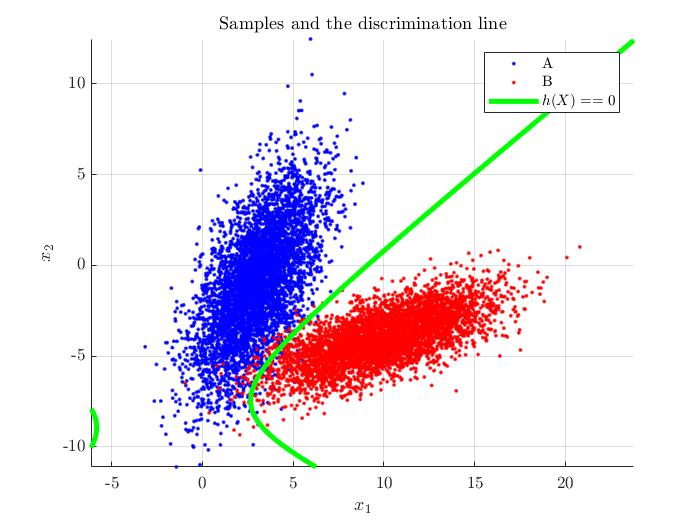

P = [0.5; 0.5];

threshold = log(P(1) / P(2));
h = -log(A.pdf_sym(X) / B.pdf_sym(X));
fimplicit(h == threshold, 'Color', 'g', 'LineWidth', line_width)
labels{end+1} = '$h(X) == 0$';

leg = legend(labels);
set(leg,'Interpreter','latex');

## Error estimation

### Histogram

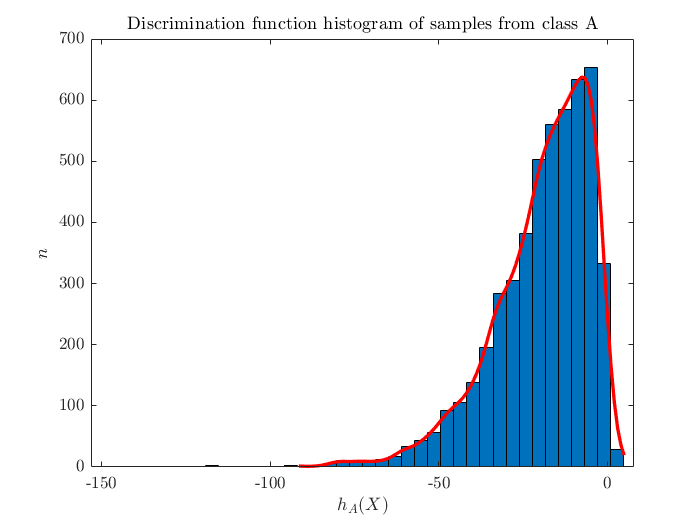

h_a = A.discrimination_function(B, 1);
n_bins = 40;
distribution_name = 'kernel';


figure();
histfit(h_a, n_bins, distribution_name);

title('Discrimination function histogram of samples from class A', "Interpreter","latex")
xlabel('$h_A(X)$', "Interpreter","latex")
ylabel('$n$', "Interpreter","latex")

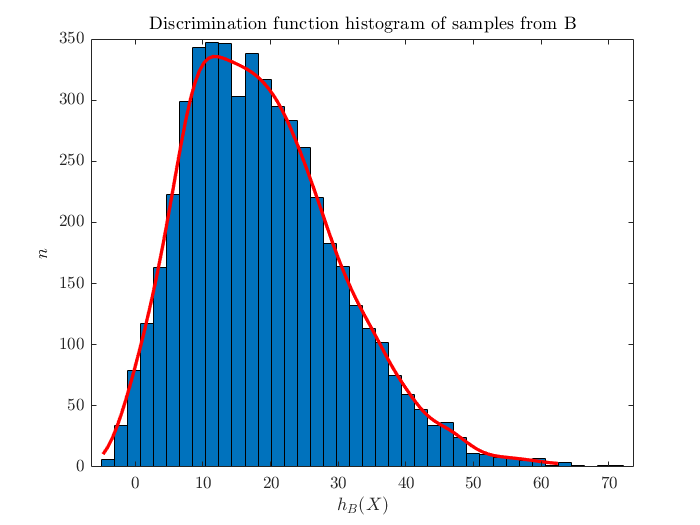

h_b = B.discrimination_function(A, 2);

figure();
histfit(h_b, n_bins, distribution_name);
title('Discrimination function histogram of samples from B', "Interpreter","latex")
xlabel('$h_B(X)$', "Interpreter","latex")
ylabel('$n$', "Interpreter","latex")

### PDF approximation

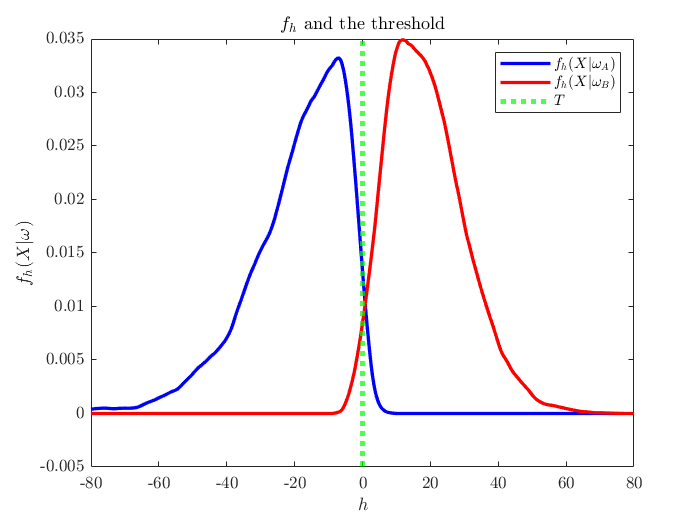

x_a = (-110:0.001:110)';
[y_a, fitobject_a] = approximate_pdf(h_a, x_a);

x_b = x_a;
[y_b, fitobject_b] = approximate_pdf(h_b, x_b);

figure();
plot(fitobject_a, 'b');
hold on;
plot(fitobject_b, 'r');

xline(threshold, 'g:', 'LineWidth', 3)
set(findall(gca, 'Type', 'Line'),'LineWidth', 2);

legend('$f_h(X|\omega_A)$', '$f_h(X|\omega_B)$', '$T$', "Interpreter","latex")
xlim([-80, 80])
title("$f_h$ and the threshold", "Interpreter","latex")
xlabel("$h$", "Interpreter","latex")
ylabel("$f_h(X|\omega)$", "Interpreter","latex")

### Error estimates

% TODO da li sam ovde nesto omasio, mozda sam zamenio 1 i 2?
h_eps_1 = integrate(fitobject_a, max(x_a), threshold);
h_eps_2 = integrate(fitobject_b, threshold, min(x_b));

freqentist_eps_1 = length(h_a(h_a > threshold)) / length(h_a) / P(1);
freqentist_eps_2 = length(h_b(h_b < threshold)) / length(h_b) / P(2);
error_approx_table = table(h_eps_1, h_eps_2, freqentist_eps_1, freqentist_eps_2)

error_approx_table = 1×4 table
    h_eps_1     h_eps_2    freqentist_eps_1    freqentist_eps_2
    ________    _______    ________________    ________________

    0.028631    0.02151         0.0196              0.0348     


total_error_h = h_eps_1 * P(1) + h_eps_2 * P(2);
total_error_freq = freqentist_eps_1 * P(1) + freqentist_eps_2 * P(2);
total_error_table = table(total_error_h, total_error_freq)

total_error_table = 1×2 table
    total_error_h    total_error_freq
    _____________    ________________

      0.025071            0.0272     
